Points=[26 21 25 19 14 25 23 19 30 24 15 30 18]

Points =     26    21    25    19    14    25    23    19    30    24    15    30    18


Teams=["Spain"; "Sweden"; "Poland"; "Austria"; "North Macedonia"; "France"; "Turkey"; "Island"; "Belgium"; "Russia"; "Scotland"; "Italy"; "Finland"]

Teams = 13×1 string array
    "Spain"
    "Sweden"
    "Poland"
    "Austria"
    "North Macedonia"
    "France"
    "Turkey"
    "Island"
    "Belgium"
    "Russia"
    "Scotland"
    "Italy"
    "Finland"


%задам потенциальный граф матрицей смежности, где веса - разность в очках между командами
Matrix_Points=[;]


Matrix_Points =

     []



for i=1:13
    for j=i+1:13
        if i==j
            Matrix_Points(i,j)=0;
        end
        Matrix_Points(i,j)=abs(Points(i)-Points(j));
        Matrix_Points(j,i)=Matrix_Points(i,j);
    end
end
Matrix_Points

Matrix_Points =      0     5     1     7    12     1     3     7     4     2    11     4     8
     5     0     4     2     7     4     2     2     9     3     6     9     3
     1     4     0     6    11     0     2     6     5     1    10     5     7
     7     2     6     0     5     6     4     0    11     5     4    11     1
    12     7    11     5     0    11     9     5    16    10     1    16     4
     1     4     0     6    11     0     2     6     5     1    10     5     7
     3     2     2     4     9     2     0     4     7     1     8     7     5
     7     2     6     0     5     6     4     0    11     5     4    11     1
     4     9     5    11    16     5     7    11     0     6    15     0    12
     2     3     1     5    10     1     1     5     6     0     9     6     6


names={'Spain';'Sweden'; 'Poland'; 'Austria'; 'North Macedonia'; 'France'; 'Turkey'; 'Island'; 'Belgium'; 'Russia'; 'Scotland'; 'Italy'; 'Finland'};
G=graph(Matrix_Points,names)%задаю исходные данные в виде графа

G =   graph with properties:

    Edges: [75×2 table]
    Nodes: [13×1 table]


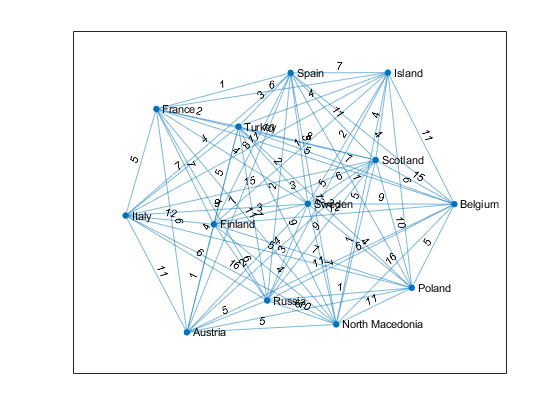

plot(G, 'EdgeLabel',G.Edges.Weight)

G1 =   graph with properties:

    Edges: [45×2 table]
    Nodes: [13×1 table]


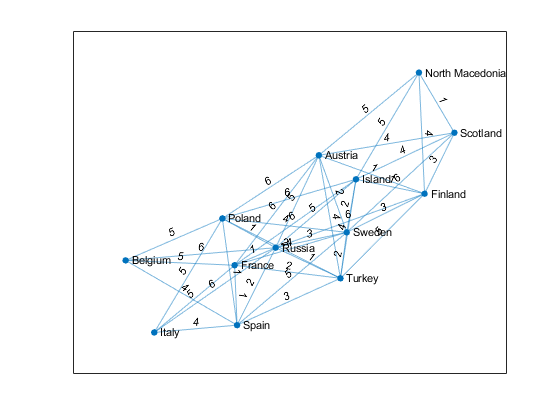

for k=1:13
    index=max(max(Matrix_Points));
    for i=1:13
        for j=1:13
            if Matrix_Points(i,j)==index
                Matrix_Points(i,j)=0;
                Matrix_Points(j,i)=0;
            end
        end
    end
    if k==8
        G1=graph(Matrix_Points,names)%граф после 4 итераций метода минимального покрывающего дерева
        plot(G1, 'EdgeLabel',G1.Edges.Weight)
    end
end

G2=graph(Matrix_Points,names)%граф после 6 итераций метода минимального покрывающего дерева

G2 =   graph with properties:

    Edges: [8×2 table]
    Nodes: [13×1 table]


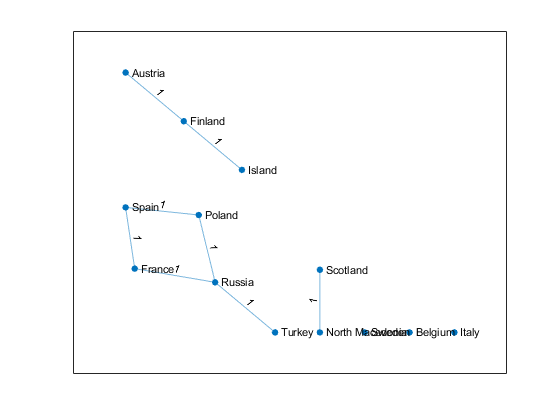

plot(G2, 'EdgeLabel',G2.Edges.Weight)